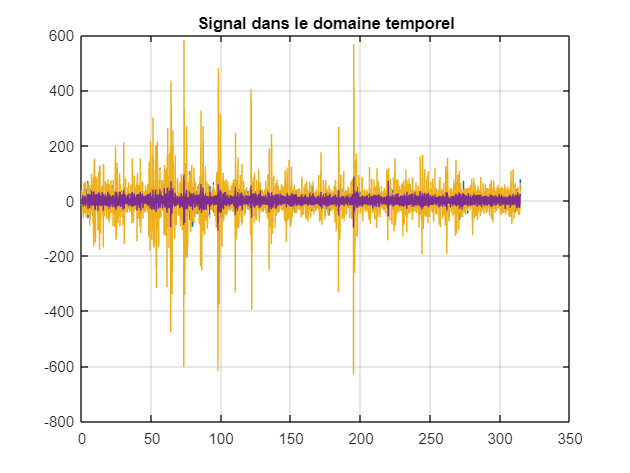

%% suppression de bruit, mouvements oculaires et signaux musculaires %%

eeg_data = csvread("data/Essai_1704_Test2.csv",1,0);
eeg_data1 = eeg_data(:,[1:8]); %toutes les électrodes
eeg_data2 = eeg_data(:,[1:4]); %électrodes 1,2,3,4

Fe = 250;
N = length(eeg_data2);
t = [0:N-1]/Fe;

figure(1)
plot(t,eeg_data2),grid
title('Signal dans le domaine temporel')

data = readmatrix("data/Essai_1704_Test2.csv");
fs = 250; %fréquence d'échantillonnage
signalDuration = size(data,1)/fs;
segmentDuration = 7;
totalSegments = 26;
startIndex = 1;
endIndex = fs * segmentDuration;
% Objectif : prendre les signaux toutes les 5 secondes (5*250) pendant
% 7 secondes (7*250)


for i = 0:26
    %0 => 250 croix + decompte
    startIndexCroix = startIndex
    endIndexCroix = endIndex
    startIndex = startIndex + fs * segmentDuration + startIndexCroix
    endIndex = endIndex + fs * segmentDuration + endIndexCroix

    croix = data(startIndexCroix:endIndexCroix,:)
    segmentData = data(startIndex:endIndex, :)

end

startIndexCroix = 1

endIndexCroix = 1750

startIndex = 1752

endIndex = 5250

croix = 1.0e+04 *

   -0.0001   -0.0017    0.0038   -0.0010    0.0151   -0.0021   -0.0014   -0.0024   -0.0000    0.0001   -0.0000    0.0001   -0.0000    0.0001    0.0060    6.9113    0.0001
   -0.0004   -0.0019    0.0035   -0.0011    0.0145   -0.0022   -0.0013   -0.0025   -0.0000    0.0001   -0.0000    0.0001   -0.0000    0.0001    0.0060    6.9114    0.0001
   -0.0005   -0.0021    0.0032   -0.0012    0.0138   -0.0021   -0.0012   -0.0025   -0.0000    0.0001   -0.0000    0.0001   -0.0000    0.0001    0.0060    6.9115    0.0001
   -0.0004   -0.0021    0.0030   -0.0011    0.0129   -0.0020   -0.0011   -0.0023   -0.0000    0.0001   -0.0000    0.0001   -0.0000    0.0001    0.0060    6.9116    0.0001
   -0.0003   -0.0020    0.0028   -0.0009    0.0120   -0.0018   -0.0010   -0.0021   -0.0000    0.0001   -0.0000    0.0001   -0.0000    0.0001    0.0060    6.9117    0.0001
   -0.0002   -0.0019    0.0025   -0.0008    0.0108   -0.0016   -0.0009   -0.0019   -0.0000    0.0001   -0.0000    0.0001   -0.

segmentData = 1.0e+04 *

    0.0046    0.0016    0.0066    0.0020    0.0110    0.0010    0.0025    0.0041   -0.0000    0.0001   -0.0000   -0.0001   -0.0000    0.0002    0.0060    7.0864    0.0001
    0.0042    0.0016    0.0064    0.0019    0.0111    0.0011    0.0023    0.0040   -0.0000    0.0001   -0.0000   -0.0001   -0.0001    0.0002    0.0060    7.0865    0.0001
    0.0036    0.0015    0.0061    0.0017    0.0111    0.0010    0.0020    0.0040   -0.0000    0.0001   -0.0000   -0.0001   -0.0001    0.0002    0.0060    7.0866    0.0001
    0.0031    0.0013    0.0059    0.0016    0.0111    0.0010    0.0019    0.0040   -0.0000    0.0001   -0.0000   -0.0002   -0.0001    0.0002    0.0060    7.0867    0.0001
    0.0027    0.0012    0.0058    0.0015    0.0110    0.0009    0.0018    0.0041   -0.0000    0.0001   -0.0000   -0.0002   -0.0001    0.0002    0.0060    7.0868    0.0001
    0.0025    0.0010    0.0058    0.0014    0.0109    0.0009    0.0019    0.0043   -0.0000    0.0001   -0.0000   -0.0002

startIndexCroix = 1752

endIndexCroix = 5250

startIndex = 5254

endIndex = 12250

croix = 1.0e+04 *

    0.0046    0.0016    0.0066    0.0020    0.0110    0.0010    0.0025    0.0041   -0.0000    0.0001   -0.0000   -0.0001   -0.0000    0.0002    0.0060    7.0864    0.0001
    0.0042    0.0016    0.0064    0.0019    0.0111    0.0011    0.0023    0.0040   -0.0000    0.0001   -0.0000   -0.0001   -0.0001    0.0002    0.0060    7.0865    0.0001
    0.0036    0.0015    0.0061    0.0017    0.0111    0.0010    0.0020    0.0040   -0.0000    0.0001   -0.0000   -0.0001   -0.0001    0.0002    0.0060    7.0866    0.0001
    0.0031    0.0013    0.0059    0.0016    0.0111    0.0010    0.0019    0.0040   -0.0000    0.0001   -0.0000   -0.0002   -0.0001    0.0002    0.0060    7.0867    0.0001
    0.0027    0.0012    0.0058    0.0015    0.0110    0.0009    0.0018    0.0041   -0.0000    0.0001   -0.0000   -0.0002   -0.0001    0.0002    0.0060    7.0868    0.0001
    0.0025    0.0010    0.0058    0.0014    0.0109    0.0009    0.0019    0.0043   -0.0000    0.0001   -0.0000   -0.0002   -0.

segmentData = 1.0e+04 *

    0.0013    0.0005    0.0039    0.0010    0.0067    0.0017    0.0010    0.0055   -0.0000    0.0001   -0.0000   -0.0001   -0.0000    0.0002    0.0060    7.4366    0.0001
    0.0012    0.0005    0.0038    0.0009    0.0069    0.0017    0.0010    0.0051   -0.0000    0.0001   -0.0000   -0.0001   -0.0000    0.0002    0.0060    7.4367    0.0001
    0.0011    0.0006    0.0037    0.0007    0.0072    0.0017    0.0011    0.0048   -0.0000    0.0001   -0.0000   -0.0001         0    0.0002    0.0060    7.4368    0.0001
    0.0012    0.0007    0.0037    0.0006    0.0075    0.0016    0.0012    0.0047   -0.0000    0.0001   -0.0000   -0.0001    0.0000    0.0002    0.0060    7.4369    0.0001
    0.0012    0.0007    0.0038    0.0006    0.0077    0.0015    0.0013    0.0047   -0.0000    0.0001   -0.0000   -0.0001         0    0.0002    0.0060    7.4370    0.0001
    0.0012    0.0006    0.0038    0.0005    0.0079    0.0014    0.0013    0.0047   -0.0000    0.0001   -0.0000   -0.0001

startIndexCroix = 5254

endIndexCroix = 12250

startIndex = 12258

endIndex = 26250

croix = 1.0e+04 *

    0.0013    0.0005    0.0039    0.0010    0.0067    0.0017    0.0010    0.0055   -0.0000    0.0001   -0.0000   -0.0001   -0.0000    0.0002    0.0060    7.4366    0.0001
    0.0012    0.0005    0.0038    0.0009    0.0069    0.0017    0.0010    0.0051   -0.0000    0.0001   -0.0000   -0.0001   -0.0000    0.0002    0.0060    7.4367    0.0001
    0.0011    0.0006    0.0037    0.0007    0.0072    0.0017    0.0011    0.0048   -0.0000    0.0001   -0.0000   -0.0001         0    0.0002    0.0060    7.4368    0.0001
    0.0012    0.0007    0.0037    0.0006    0.0075    0.0016    0.0012    0.0047   -0.0000    0.0001   -0.0000   -0.0001    0.0000    0.0002    0.0060    7.4369    0.0001
    0.0012    0.0007    0.0038    0.0006    0.0077    0.0015    0.0013    0.0047   -0.0000    0.0001   -0.0000   -0.0001         0    0.0002    0.0060    7.4370    0.0001
    0.0012    0.0006    0.0038    0.0005    0.0079    0.0014    0.0013    0.0047   -0.0000    0.0001   -0.0000   -0.0001    0.

segmentData = 1.0e+04 *

    0.0018    0.0009   -0.0050    0.0004   -0.0136    0.0007   -0.0032   -0.0007   -0.0000    0.0001   -0.0000   -0.0000   -0.0001    0.0003    0.0060    8.1370    0.0001
    0.0020    0.0012   -0.0042    0.0005   -0.0131    0.0007   -0.0026    0.0003   -0.0000    0.0001   -0.0000         0   -0.0001    0.0003    0.0060    8.1371    0.0001
    0.0020    0.0013   -0.0036    0.0005   -0.0129    0.0006   -0.0020    0.0009   -0.0000    0.0001   -0.0000    0.0000   -0.0001    0.0002    0.0060    8.1372    0.0001
    0.0018    0.0012   -0.0033    0.0004   -0.0130    0.0004   -0.0012    0.0012    0.0000    0.0001   -0.0000    0.0000   -0.0001    0.0002    0.0060    8.1373    0.0001
    0.0015    0.0010   -0.0032    0.0002   -0.0133    0.0003   -0.0004    0.0013    0.0000    0.0001   -0.0000   -0.0000   -0.0001    0.0002    0.0060    8.1374    0.0001
    0.0012    0.0006   -0.0032   -0.0000   -0.0137    0.0001    0.0002    0.0012    0.0000    0.0001   -0.0000   -0.0000

startIndexCroix = 12258

endIndexCroix = 26250

startIndex = 26266

endIndex = 54250

croix = 1.0e+04 *

    0.0018    0.0009   -0.0050    0.0004   -0.0136    0.0007   -0.0032   -0.0007   -0.0000    0.0001   -0.0000   -0.0000   -0.0001    0.0003    0.0060    8.1370    0.0001
    0.0020    0.0012   -0.0042    0.0005   -0.0131    0.0007   -0.0026    0.0003   -0.0000    0.0001   -0.0000         0   -0.0001    0.0003    0.0060    8.1371    0.0001
    0.0020    0.0013   -0.0036    0.0005   -0.0129    0.0006   -0.0020    0.0009   -0.0000    0.0001   -0.0000    0.0000   -0.0001    0.0002    0.0060    8.1372    0.0001
    0.0018    0.0012   -0.0033    0.0004   -0.0130    0.0004   -0.0012    0.0012    0.0000    0.0001   -0.0000    0.0000   -0.0001    0.0002    0.0060    8.1373    0.0001
    0.0015    0.0010   -0.0032    0.0002   -0.0133    0.0003   -0.0004    0.0013    0.0000    0.0001   -0.0000   -0.0000   -0.0001    0.0002    0.0060    8.1374    0.0001
    0.0012    0.0006   -0.0032   -0.0000   -0.0137    0.0001    0.0002    0.0012    0.0000    0.0001   -0.0000   -0.0000   -0.

segmentData = 1.0e+05 *

    0.0001    0.0001    0.0002    0.0000    0.0006    0.0000   -0.0002   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0006    0.9538    0.0000
    0.0000    0.0001    0.0002    0.0000    0.0006    0.0000   -0.0002   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0006    0.9538    0.0000
    0.0000    0.0001    0.0001   -0.0000    0.0006   -0.0000   -0.0002   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0006    0.9538    0.0000
    0.0000    0.0001    0.0001   -0.0000    0.0005   -0.0000   -0.0002   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0006    0.9538    0.0000
    0.0000    0.0000    0.0001   -0.0000    0.0005   -0.0000   -0.0002   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0006    0.9538    0.0000
    0.0001    0.0000    0.0001    0.0000    0.0005   -0.0000   -0.0002   -0.0000   -0.0000    0.0000   -0.0000   -0.0000

startIndexCroix = 26266

endIndexCroix = 54250

startIndex = 54282

endIndex = 110250

croix = 1.0e+05 *

    0.0001    0.0001    0.0002    0.0000    0.0006    0.0000   -0.0002   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0006    0.9538    0.0000
    0.0000    0.0001    0.0002    0.0000    0.0006    0.0000   -0.0002   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0006    0.9538    0.0000
    0.0000    0.0001    0.0001   -0.0000    0.0006   -0.0000   -0.0002   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0006    0.9538    0.0000
    0.0000    0.0001    0.0001   -0.0000    0.0005   -0.0000   -0.0002   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0006    0.9538    0.0000
    0.0000    0.0000    0.0001   -0.0000    0.0005   -0.0000   -0.0002   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0006    0.9538    0.0000
    0.0001    0.0000    0.0001    0.0000    0.0005   -0.0000   -0.0002   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.

Index in position 1 exceeds array bounds. Index must not exceed 78584.

%% filtrer sous forme d'échantillons %%

% prendre les parties de tests (7 secondes environ)

%% supp bruit %%

% sur les électrodes 1,2,3,4 %

fc = 35

fc = 35

[b,a] = butter(4,fc/(fs/2),"low") %filtre passe-bas (supprimer bruit à haute fréquence)

b =     0.0148    0.0593    0.0890    0.0593    0.0148


a =     1.0000   -1.7293    1.4461   -0.5713    0.0917


eeg_data_filtered = filtfilt(b,a,eeg_data2); % appliquer filtre aux données EEG

fc = 12 

fc = 12

[b,a] = butter(4,fc/(fs/2),"high") %filtre passe-haut (supprimer bruit à basse fréquence)

b =     0.6731   -2.6925    4.0388   -2.6925    0.6731


a =     1.0000   -3.2133    3.9348   -2.1689    0.4531


eeg_data_filtered = filtfilt(b,a, eeg_data_filtered); % appliquer filtre aux données EEG

save('ee_data_filtered.mat', "eeg_data_filtered")



%% Définition des régions d'intérêt %%

roi1 = [1 2 3 5 6 7] %région d'intéret pour mouvement ou pensée à droite

roi1 =      1     2     3     5     6     7


roi2 = [1 3 4 5 7 8] %région d'intéret pour mouvement ou pensée à gauche

roi2 =      1     3     4     5     7     8



roi3 = eeg_data_filtered(:,[1 2 3]) %région d'intérêt pour mvt ou pensée à droite (4 électrodes)

roi3 =     0.0509    0.1024    0.0362
    1.1445    1.5080    1.2276
    1.5067    2.4540    1.9160
    0.8532    2.6750    1.8993
   -0.5342    2.1681    1.3233
   -1.9979    1.1665    0.5266
   -2.8867    0.0234   -0.1996
   -2.8903   -0.9342   -0.7546
   -2.1439   -1.5185   -1.1954
   -1.0756   -1.7115   -1.5831


roi4 = eeg_data_filtered(:,[1 3 4]) %région d'intérêt pour mvt ou pensée à gauche (4 électrodes)

roi4 =     0.0509    0.0362    0.1914
    1.1445    1.2276    1.1936
    1.5067    1.9160    1.8296
    0.8532    1.8993    1.9184
   -0.5342    1.3233    1.4976
   -1.9979    0.5266    0.7587
   -2.8867   -0.1996   -0.0732
   -2.8903   -0.7546   -0.8330
   -2.1439   -1.1954   -1.4363
   -1.0756   -1.5831   -1.8397


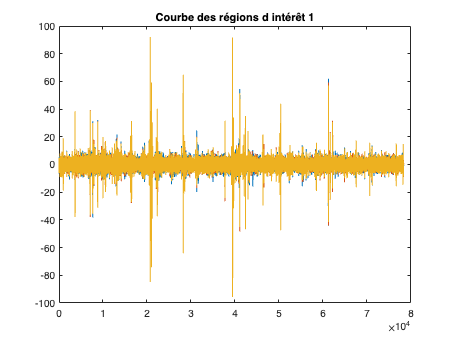


% extraire les signaux de chaque ROI


plot(roi3);
title('Courbe des régions d intérêt 1');

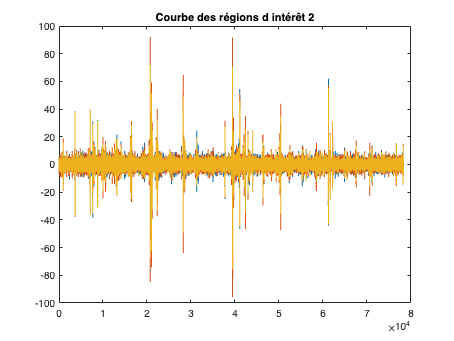

plot(roi4);
title('Courbe des régions d intérêt 2');


%% scalogramme %%



%% supp artefacts oculaires %%


%corr() 

%% supp artefacts musculaires %%

%cleanline()


% sélection des fenêtres d'échantillonnage

% analyse de fréquence (transformée en ondelettes)

% analyse synchronisation entre différentes régions du cerveau :
% utilisation corrélation croisée ou cohérence de phase

% analyse des caractéristiques : pics ondes cérébrales, pics puissance,
% latences etc

% classif (pas notre partie)